##  Задание 1. Компенсирующий регулятор по состоянию. 

Начальные условия задания

A = [12 -1 14; 
    6 0 6; 
    -6 -2 -8]; mat2tex(A,2);

\begin{bmatrix}
    12 & -1 & 14 \\
    6 & 0 & 6 \\
    -6 & -2 & -8 \\
\end{bmatrix}


B = [11; 7; -7]; mat2tex(B,2);

\begin{bmatrix}
    11 \\
    7 \\
    -7 \\
\end{bmatrix}



Bf = [0 2 -1 0; 
      0 0 0 0; 
      0 -2 0 0]; mat2tex(Bf,2);

\begin{bmatrix}
    0 & 2 & -1 & 0 \\
    0 & 0 & 0 & 0 \\
    0 & -2 & 0 & 0 \\
\end{bmatrix}


C = [-2 2 -1]; mat2tex(C,2);

\begin{bmatrix}
    -2 & 2 & -1 \\
\end{bmatrix}


Cz = [2 1 3]; mat2tex(Cz,2);

\begin{bmatrix}
    2 & 1 & 3 \\
\end{bmatrix}



G = [-40 16 9 -7;
    -64 25 14 -12; 
    -26 11 7 -3; 
    48 -18 -14 8]; mat2tex(G,2);

\begin{bmatrix}
    -40 & 16 & 9 & -7 \\
    -64 & 25 & 14 & -12 \\
    -26 & 11 & 7 & -3 \\
    48 & -18 & -14 & 8 \\
\end{bmatrix}



D = [6; -6; -4; -5]; mat2tex(D,2);

\begin{bmatrix}
    6 \\
    -6 \\
    -4 \\
    -5 \\
\end{bmatrix}


% Dz = [-8 -2 8 -5]; % По условию здесь выход нулевой...
Dz = [0 0 0 0]; 

w_0 = [1; 1; 1; 1];
x_0 = [0; 0; 0];

Анализ устойчивости системы

eig(A)

ans =    3.0000 + 3.0000i
   3.0000 - 3.0000i
  -2.0000 + 0.0000i



rank(ctrb(A,B))

ans = 2

rank(obsv(A,C))

ans = 3

e = eig(G)

e =    0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 2.0000i
   0.0000 - 2.0000i


Синтезируем компоненту K1 методом LQR-регулятора

Q = eye(3);
R = 1;
[K1,~,~] = lqr(A, B, Q, R);
K1 = -K1

K1 =     8.7057   -8.6171    8.4715


mat2tex(K1,2);

\begin{bmatrix}
    8.71 & -8.62 & 8.47 \\
\end{bmatrix}



eig(A + B*K1)

ans =   -14.3859
   -3.4708
   -2.0000


cvx_begin sdp;
variable P(3,4);
variable Y(1,4);

P*G - A*P == B*Y + Bf;
Cz*P == 0;
cvx_end;

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.5e-01|4.6e+03|8.3e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.884|9.5e-02|5.3e+02|2.2e+04| 0.000000e+00  4.480914e+03| 0:0:00| chol  1  1 
 2|1.000|0.922|1.1e-04|4.1e+01|1.2e+03| 0.000000e+00 -1.149022e+02| 0:0:00| chol  1  1 
 3|1.000|0.988|2.9e-06|4.8e-01|1.1e+01| 0.000000e+00 -1.317534e+00| 0:0:00| chol  2  2 
 4|1.000|0.98

K2 = Y - K1*P

K2 =    14.7357   -5.9370   -9.6169    1.3042


mat2tex(K1,2);

\begin{bmatrix}
    8.71 & -8.62 & 8.47 \\
\end{bmatrix}


###  Выполнить следующее компьютерное моделирование...

### Разомкнутая система, u=0...

B = [0; 0; 0]; % Простым взмахом руки
out = sim('ex1.slx','ReturnWorkspaceOutputs','on');
t = out.tout;
x = out.x.data';

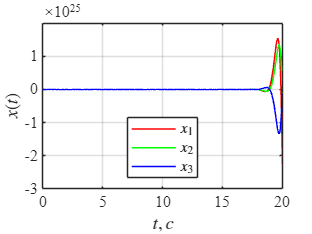

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("x1")

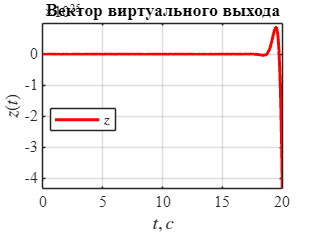

z = out.z.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, z, 'r', 'LineWidth', 2);
title('Вектор виртуального выхода')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$z$', ...
    'Location','best', 'Interpreter','latex')
save_file("z1")

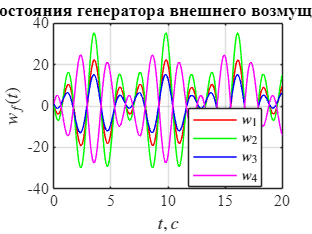

w = out.w.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, w(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, w(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, w(3, :), 'b', 'LineWidth', 1.0);
hold on;
plot(t, w(4, :), 'magenta', 'LineWidth', 1.0);
title('Состояния генератора внешнего возмущения')
xlabel('$t,c$','Interpreter','latex')
ylabel('$w_f(t)$', 'Interpreter','latex')
grid on
legend('$w_1$','$w_2$','$w_3$','$w_4$', ...
    'Location','best', 'Interpreter','latex')
save_file("w1")

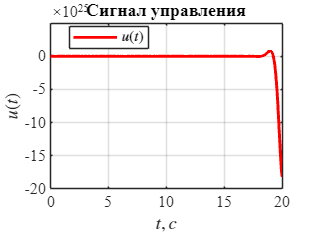

u = out.u.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, u, 'r', 'LineWidth', 2);
title('Сигнал управления')
xlabel('$t,c$','Interpreter','latex')
ylabel('$u(t)$', 'Interpreter','latex')
grid on
legend('$u(t)$', ...
    'Location','best', 'Interpreter','latex')
save_file("u1")

### Замкнули регулятором только с K1 компонентой

B = [11; 7; -7]; % возвращаем всё на свои места
% K2 = [14.7357	-5.9370	-9.6169	1.3042];
K2 = [0 0 0 0];
out = sim('ex1.slx','ReturnWorkspaceOutputs','on');
t = out.tout;
x = out.x.data';

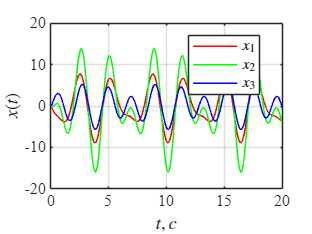

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("x2")

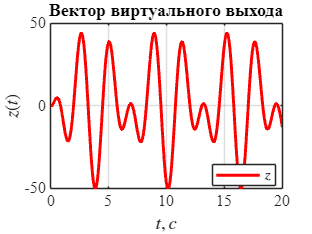

z = out.z.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, z, 'r', 'LineWidth', 2);
title('Вектор виртуального выхода')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$z$', ...
    'Location','best', 'Interpreter','latex')
save_file("z2")

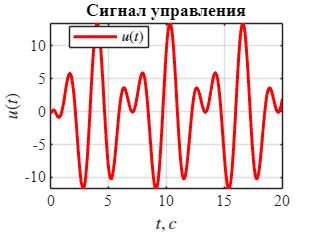

u = out.u.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, u, 'r', 'LineWidth', 2);
title('Сигнал управления')
xlabel('$t,c$','Interpreter','latex')
ylabel('$u(t)$', 'Interpreter','latex')
grid on
legend('$u(t)$', ...
    'Location','best', 'Interpreter','latex')
save_file("u2")

### Замкнули полным регулятором

K2 = [14.7357	-5.9370	-9.6169	1.3042]; % возвращаем всё на свои места
out = sim('ex1.slx','ReturnWorkspaceOutputs','on');
t = out.tout;
x = out.x.data';

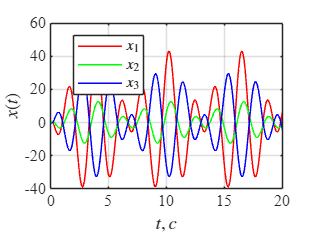

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("x3")

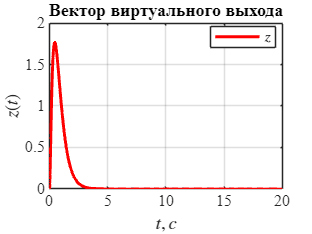

z = out.z.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, z, 'r', 'LineWidth', 2);
title('Вектор виртуального выхода')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$z$', ...
    'Location','best', 'Interpreter','latex')
save_file("z3")

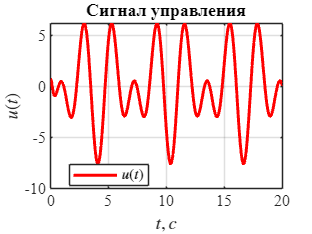

u = out.u.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, u, 'r', 'LineWidth', 2);
title('Сигнал управления')
xlabel('$t,c$','Interpreter','latex')
ylabel('$u(t)$', 'Interpreter','latex')
grid on
legend('$u(t)$', ...
    'Location','best', 'Interpreter','latex')
save_file("u3")

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab12\latex12\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end